W_100_Heights = reshape(cell2mat(WHITE_100_Heights(:,3)),[],15);
W_100_H0_H6 = [WHITE{10,3}; W_100_Heights];
AS_wavelengths = [410, 440, 470, 510, 550, 583, 620, 670];
VEML_wavelengths = [650, 550, 450];

% plot(AS_wavelengths,W_100_H0_H6(1,1:8))
% hold on
% for i = 2:6
%     plot(AS_wavelengths,W_100_H0_H6(i,1:8))
% end
% hold off

distances = flip([0, 4, 7.8, 11.5, 14.5, 17.5, 20.5]);

% plot(distances,W_100_H0_H6(:,3))
% hold on
% for i = 2:9
%     plot(distances,W_100_H0_H6(:,i))
% end
% legend("CH1","CH2","CH3","CH4","CH5","CH6","CH7","CH8","CLEAR")
% hold off

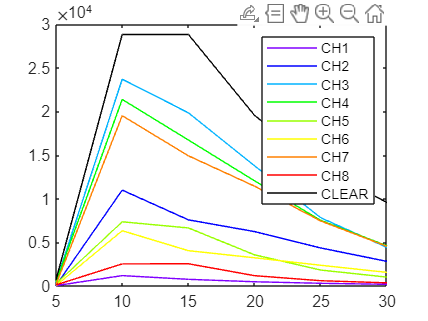

d = 30:-5:5;
DIST_2 = reshape(cell2mat(DIST(:,2)),[],15); % integrationtime = 160ms
DIST_2(:,1);
plot(d,DIST_2(:,1:9));
legend("CH1","CH2","CH3","CH4","CH5","CH6","CH7","CH8","CLEAR");
ax = gca;
ax.ColorOrder = AS_Colours;

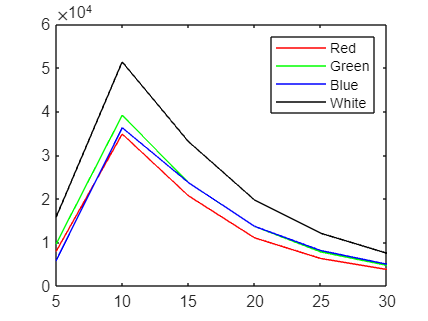

plot(d,DIST_2(:,11:14));
legend("Red", "Green", "Blue", "White")
ax = gca;
ax.ColorOrder = VEML_Colours;

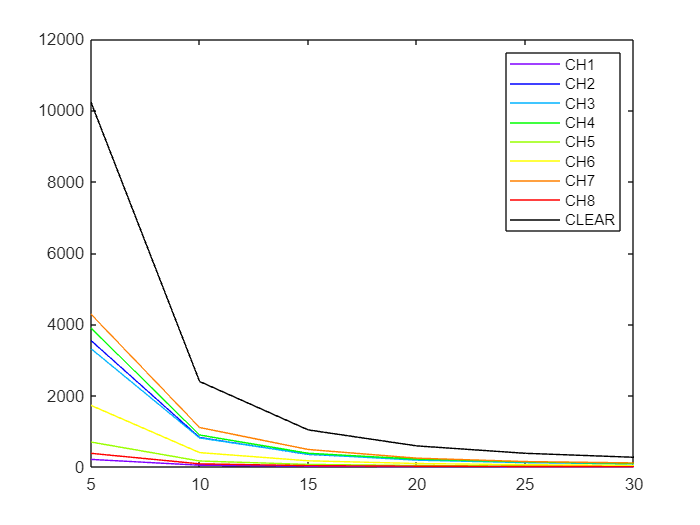

d = 30:-5:5;
DIST_AS = reshape(cell2mat(DISTas(:,2)),[],15); % integrationtime = 160ms
DIST_AS(:,1);
plot(d,DIST_AS(:,1:9));
legend("CH1","CH2","CH3","CH4","CH5","CH6","CH7","CH8","CLEAR");
ax = gca;
ax.ColorOrder = AS_Colours;

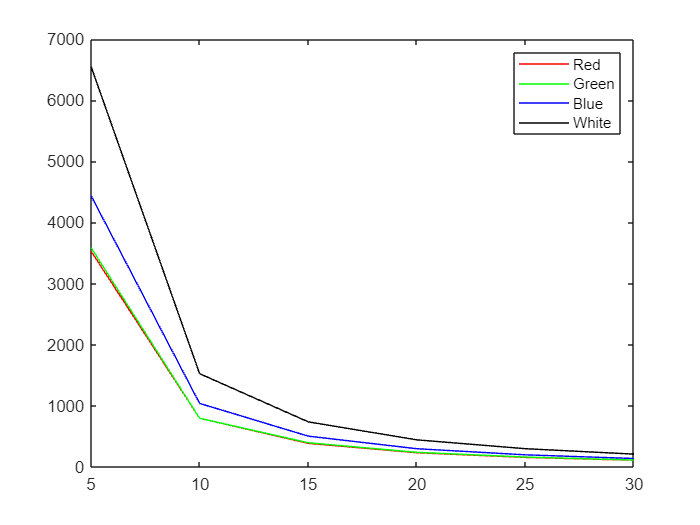


DIST_VEML = reshape(cell2mat(DISTveml(:,2)),[],15); % integrationtime = 160ms
plot(d,DIST_VEML(:,11:14));
legend("Red", "Green", "Blue", "White")
ax = gca;
ax.ColorOrder = VEML_Colours;

function COLOUR_Scaled = scale(COLOUR)
    factors = [4, 2, 1, 0.5, 0.25, 0.125];
    COLOUR_Scaled = cell(6,6);
    for j = 1:10
        for i = 1:6
            COLOUR_Scaled{j,i} = COLOUR{j, i}.*factors(i);
        end
    end
end